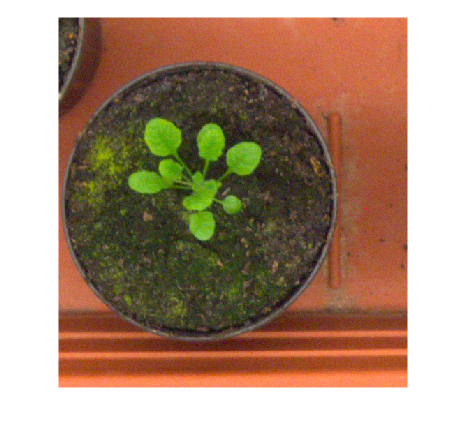

%I = imread("G:\Documents\Github\LeafSAM\dataset\Komatsuna\rgbd_plant\rgb_01_008_02.png");
%I = imread("G:\Documents\Github\LeafSAM\dataset\DenseLeaves_MSU\DenseLeaves\train\leaf00162_000_img.png")
I = imread("G:\Documents\Github\LeafSAM\dataset\CVPPP\train\images\A1\plant012_rgb.png");
I_rgb = im2double(I);
imshow(I_rgb)

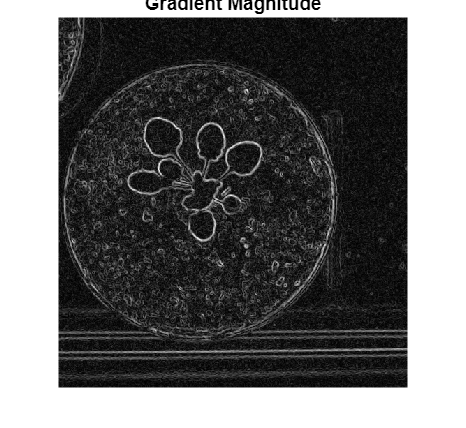

gmag = imgradient(rgb2gray(I));
imshow(gmag,[])
title("Gradient Magnitude")

I_lab = rgb2lab(I_rgb);
I_a = I_lab(:,:,2);

[L,N] = superpixels(I_lab,5000, IsInputLab=true);
meanColors = regionprops(L, I_a, 'MeanIntensity');
meanColors = [meanColors.MeanIntensity];

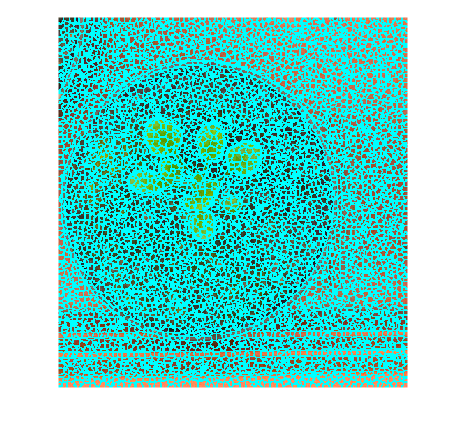

BW = boundarymask(L);
imshow(imoverlay(I_rgb,BW,'cyan'))

threshold = -15

threshold = -15

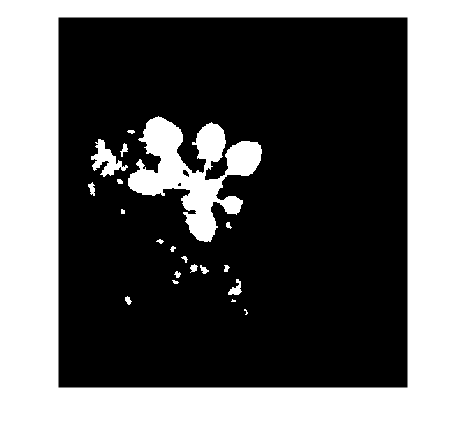

plantSuperpixels = find(meanColors < threshold);
plantMask = ismember(L, plantSuperpixels);
FG_overlay = imoverlay(imoverlay(I_rgb,BW,'cyan'), ~plantMask, "black");
FG = imoverlay(I_rgb, ~plantMask, "black");
imshow(plantMask)

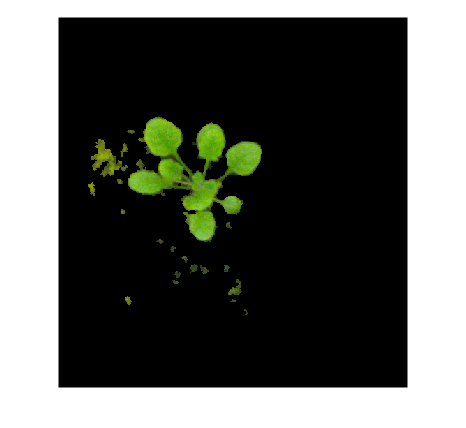

imshow(FG)

FG_lab = rgb2lab(FG);


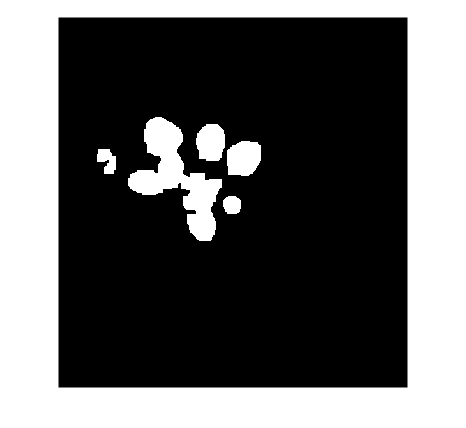

edges = edge(plantMask, 'Canny');
%plantMask = edges+plantMask;
se1 = strel('square',10);
plantMask = imopen(plantMask,se1);
imshow(plantMask)

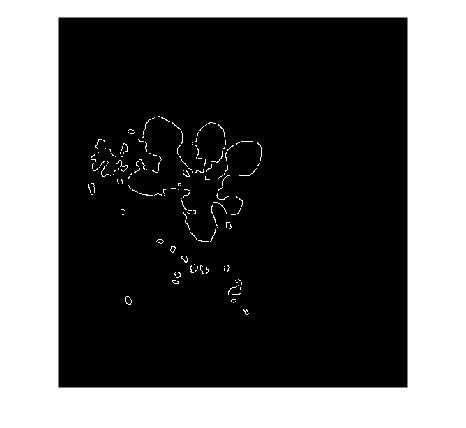

imshow(edges)

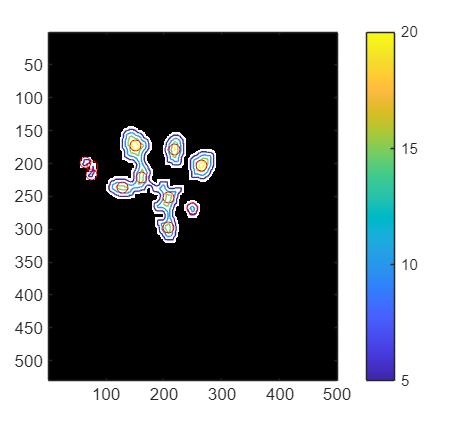

distanceMap = bwdist(~plantMask);
centroids = regionprops(plantMask, distanceMap, 'Centroid');
centroids = cat(1, centroids.Centroid);
TF = islocalmax2(distanceMap, "MinProminence",5, MinSeparation=5);
maxval = distanceMap(TF);

Irgb = cat(3,plantMask,plantMask,plantMask);
% Plot the image and some contours in color
image(Irgb)
% Display the binary mask in black and white
hold on
imcontour(distanceMap)
[row,col]=size(plantMask);
[X,Y] = meshgrid(1:col,1:row);
colorbar

%for i = 1: numel(maxval)
plot3(X(TF),Y(TF),maxval, 'ro')
hold off

coordinates=[X(TF),Y(TF)]

coordinates =     65   198
    74   217
    77   204
   128   237
   150   173
   161   221
   207   298
   208   252
   218   179
   249   268


numel_row = numel(coordinates(:,1))

numel_row = 11

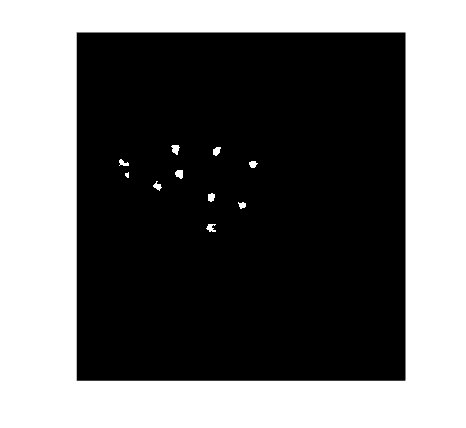

% Find the superpixel for each point

markers = zeros(numel_row, 1);
for i = 1:numel_row
    x = coordinates(i, 1);
    y = coordinates(i, 2);
    markers(i) = L(y, x);
end
maskMarker = ismember(L, markers);
imshow(maskMarker)

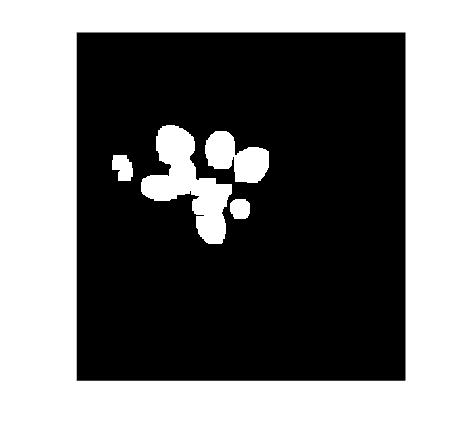

% Create a structuring element for dilation (e.g., 3x3 square)
se = strel('disk',3); % Adjust size as needed

% Dilate the binary mask
D = imdilate(plantMask, se);
imshow(D)

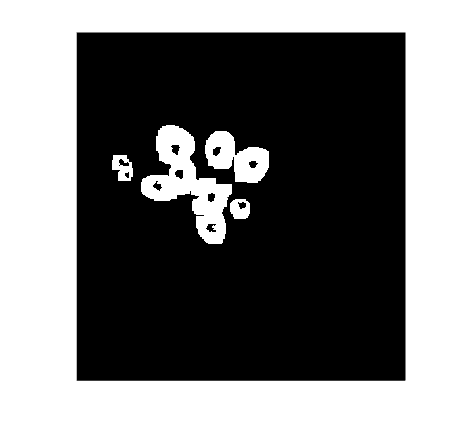

gmag2 = imimposemin(gmag, ~D | maskMarker);
L = watershed(gmag2);
imshow(gmag2)

L = L-1;

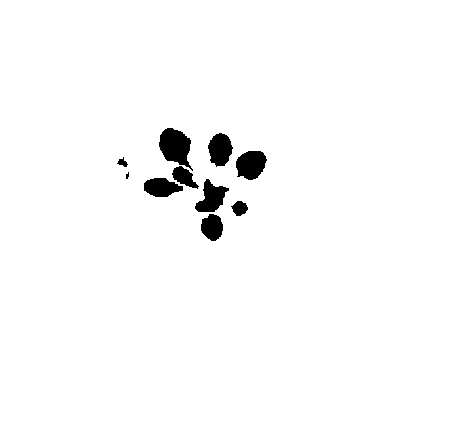

labels = imdilate(L==0,ones(3,3));
imshow(labels)

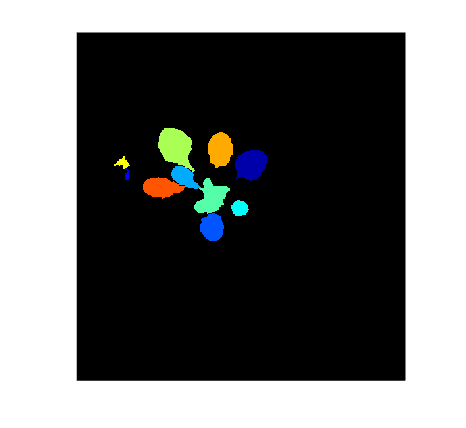

Lrgb = label2rgb(L,"jet","k","shuffle");
imshow(Lrgb)

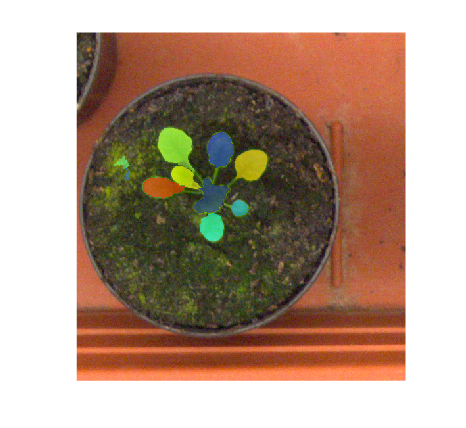

leafOverlay = labeloverlay(I_rgb,L);
imshow(leafOverlay)